clear all, close all, clc

load('data/2017-08-31-ks_analysis.mat')
whos

  Name               Size               Bytes  Class     Attributes

  epm                1x1               841024  struct              
  exptAges           2x1                  244  cell                
  exptRegions        4x1                  512  cell                
  gr                 1x1               422265  struct              
  kstable          336x9             53448809  table               
  sc                 1x1               998745  struct              
  timestamp          1x20                  40  char                
  ym                 1x1              1731200  struct              



B = ym.CrusI.Adult

B = struct with fields:
           behavior: [51×14 table]
           dataPath: 'data/BehavioralDataMatrix.April14_clean_8_17_2017.xlsx'
             isCtrl: [51×1 logical]
         metafields: {'Age'  'Region'  'Condition'}
       metricLabels: {'YM_AcqInitialLR'  'YM_AcqSecondaryLR'  'YM_AcqAbility'  'YM_EarlyRevInitialLR'  'YM_EarlyRevSecondaryLR'  'YM_EarlyRevAbility'  'YM_LateRevInitialLR'  'YM_LateRevAbility'  'YM_Distance'  'YM_Velocity'}
             params: [1×1 struct]
               mice: {51×1 cell}
            metrics: [51×10 double]
           isMetric: [0 0 0 0 1 1 1 1 1 1 1 1 1 1]
       descriptions: {1×10 cell}
              units: {'% correct'  'change in % correct'  'average % correct'  '% correct'  'change in % correct'  '% correct'  '% correct'  'average % correct'  'mm'  'mm/s'}
                pcs: [1×1 struct]
         assay_name: 'Ymaze'
       assay_abbrev: 'YM'
                raw: [51×10 table]
                  X: [51×10 table]
                pca: [51×10 


% already normalized/projected:
allmice_amps = B.pca{:,:};
untreat_amps = B.pca{B.isCtrl,:}; % controls
treated_amps = B.pca{~B.isCtrl,:}; % experimentals

num_untreat = size(untreat_amps,1)

num_untreat =     41

num_treated = size(treated_amps,1)

num_treated =     10

d = size(allmice_amps,2) % number of pcs

d =     10

N = 10000; % number of bootstrap samples
% k = size(untreat_amps,1); % number of mice per sampling
k = size(treated_amps,1); % number of mice per sampling
alpha = 0.05; % significance level

tic;
sample_pval = NaN(N,d);
sample_var = NaN(N,d);
sample_sig_var = NaN(N,1);
sample_num_sig = NaN(N,1);
for i = 1:N
    sample_amps = datasample(allmice_amps,k); % random subsample
    sample_latent = sum(sample_amps .^ 2) ./ size(sample_amps,1); % compute latents (eigenvalues of covariance matrix)
    
    [~,sample_pval(i,:)] = ttest2(untreat_amps,sample_amps); % significance test
    is_sig = sample_pval(i,:) < alpha;
    
    sample_var(i,:) = sample_latent; % variance per pc
    sample_sig_var(i) = sum(sample_latent(is_sig)); % sum of variance for significant pcs
    sample_num_sig(i) = sum(is_sig); % count of significant pcs
end
toc

Elapsed time is 4.284599 seconds.


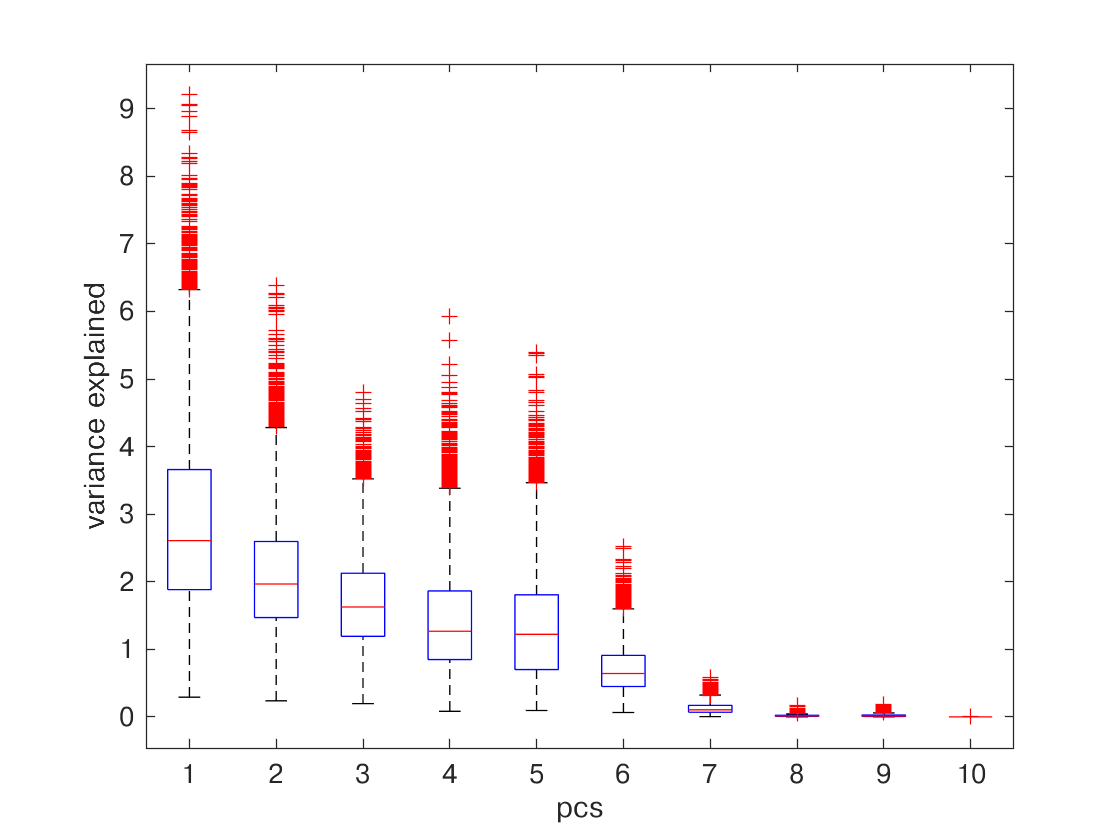

figure,boxplot(sample_var)
xlabel('pcs'),ylabel('variance explained')

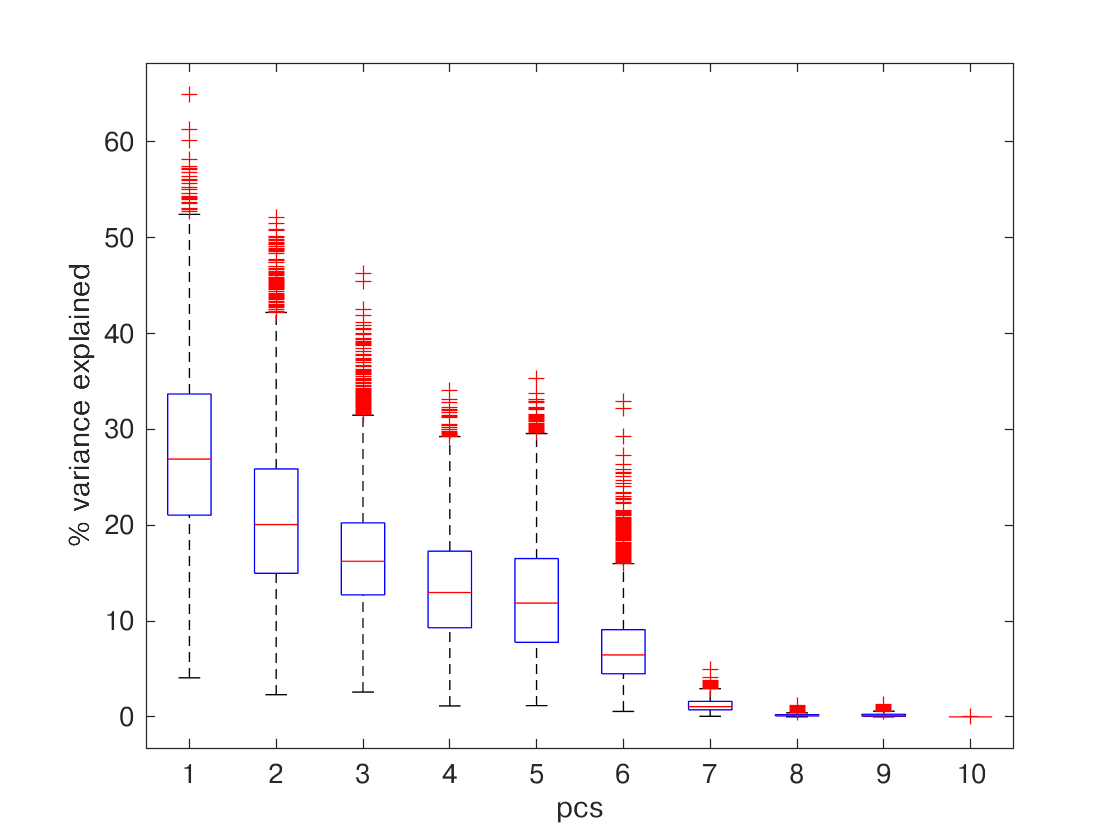


figure,boxplot(sample_var ./ sum(sample_var,2) * 100)
xlabel('pcs'),ylabel('% variance explained')

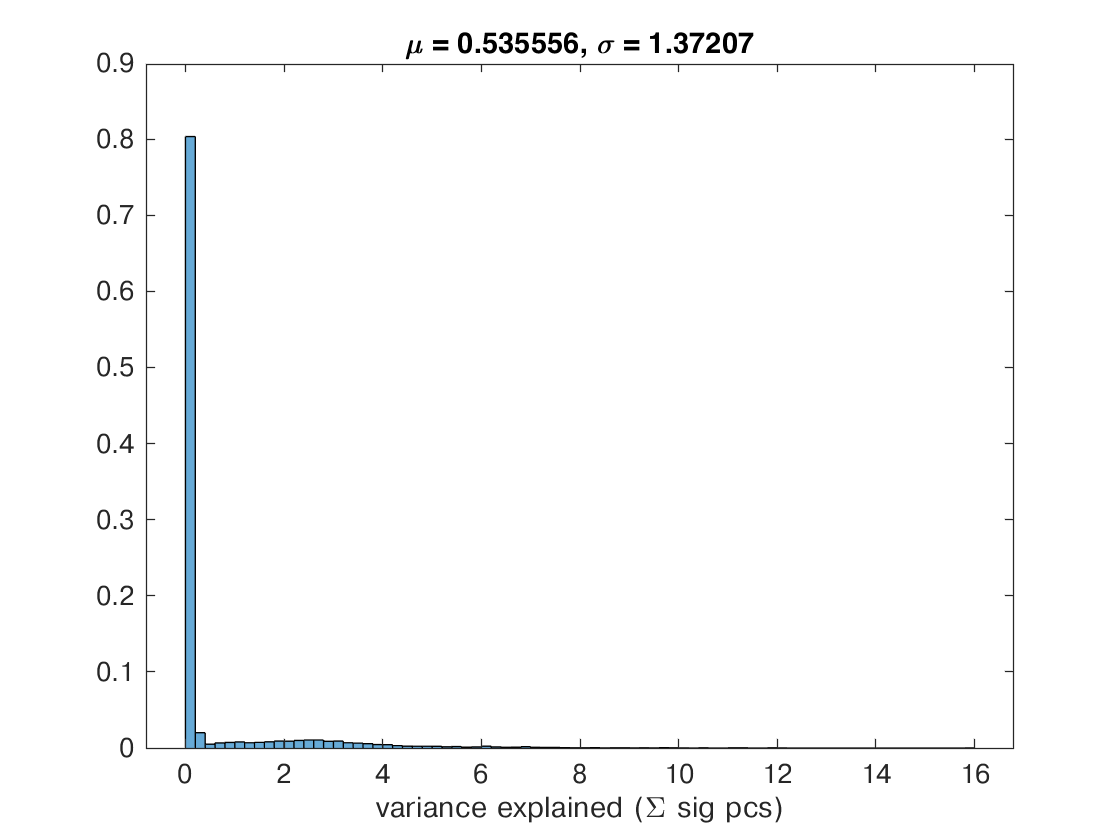


figure,histogram(sample_sig_var, 'Normalization','probability'),xlabel('variance explained (\Sigma sig pcs)')
title(sprintf('\\mu = %g, \\sigma = %g', mean(sample_sig_var), std(sample_sig_var)))

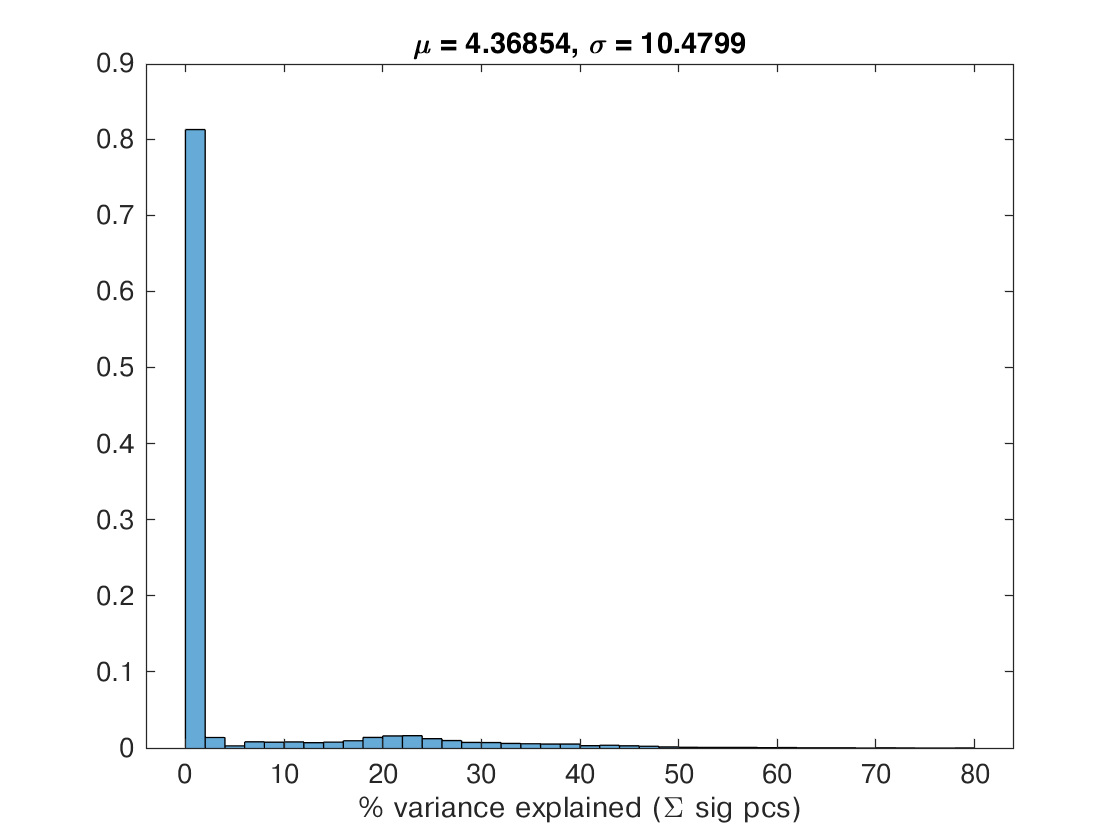


sample_sig_var_perc = sample_sig_var ./ sum(sample_var,2) * 100;
figure,histogram(sample_sig_var_perc, 'Normalization','probability'),xlabel('% variance explained (\Sigma sig pcs)')
title(sprintf('\\mu = %g, \\sigma = %g', mean(sample_sig_var_perc), std(sample_sig_var_perc)))

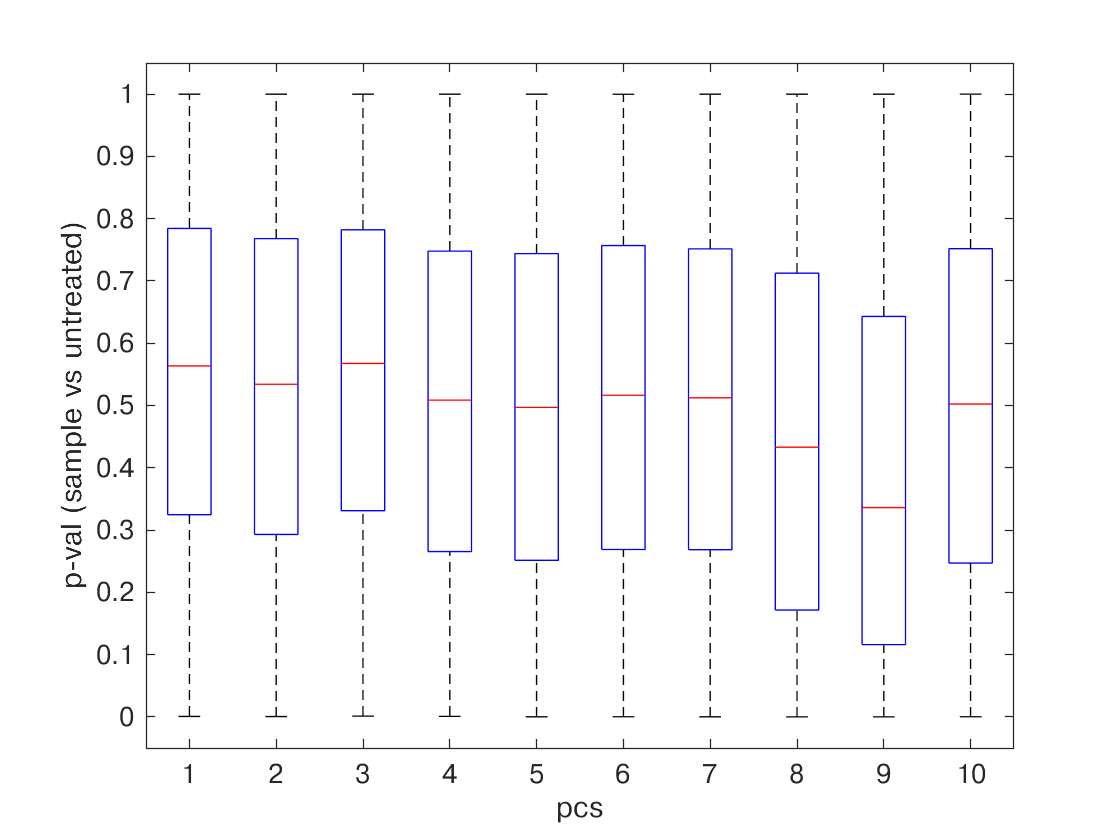


figure,boxplot(sample_pval),ylabel('p-val (sample vs untreated)'),xlabel('pcs')

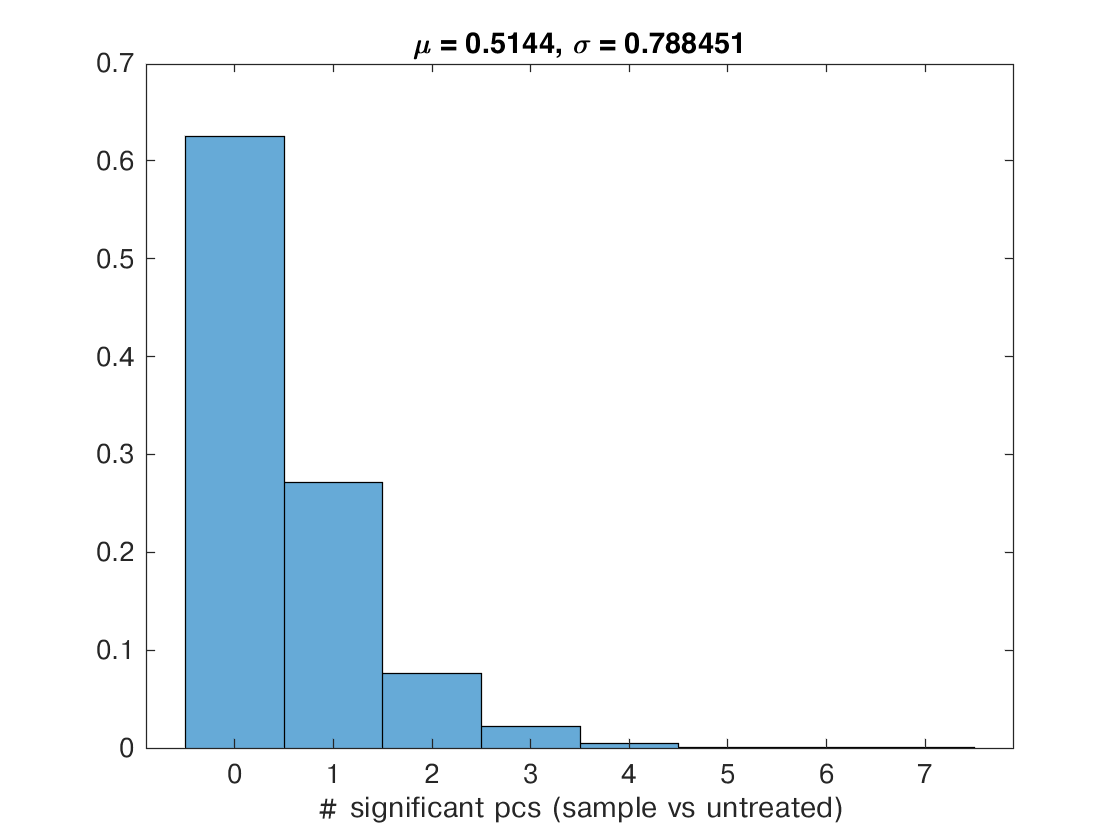


figure,histogram(sample_num_sig,'Normalization','probability'),xlabel('# significant pcs (sample vs untreated)')
title(sprintf('\\mu = %g, \\sigma = %g', mean(sample_num_sig), std(sample_num_sig)))